# Chapter 1: The French-DeGroot model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 1.1 The French-DeGroot model of opinion formation

Describes a DT process of opinion formation in a group of $n$ agents, whose opinions are $x_1, \dots, x_n \text{ with } x_i\in\mathbb R$

System dynamics is described by the stochastic matrix $W = (w_{ij}) \in \mathbb R^{n \times n}$ where $w_{ij}>0, j=1, \dots, n$ defines the influence of agent $j$ on the opinion of agent $i$ at each time-step.

Hence the system equation is 

                                                             (M1.1)   $x(k+1) = Wx(k) = \sum_{j = 1}^nw_{ij}x_j(k) \forall i, \ k = 0, 1 , \dots$

The self-influence weight $w_{ii} \ge 0
$ indicates the agent's openness to the assimilation of other's opinions:

- $w_{ii} = 0
$ "open-minded" (completely relies on others' opinions)

- $w_{ii} = 1 \text{ and } w_{ij}=0 \forall j \neq i $ "stubborn" (anchored to its initial opinion $x_i (k) \equiv x_i(0) \text{ for } k = 0, 1 ,\dots
$

Agent's opinions can also be vectors $x^i = (x_{1i}, \dots,x_{mi})$, hence we get the opinion matrix $X = (x_{ii})\in \mathbb R ^ {n \times m}$ and we can rewrite the system dynamics as 

                                                                            (M1.2)    $X(k+1) = WX(k), \ k = 0,1, \dots$

Every column $x_i(k) = (x_{1i}(k),\dots x_{ni}(k))^T \in \mathbb R ^n \text{ of } X(k)$ evolves in accordance to M1. Hence M2 with a general stochastic matrix W is referred to as the French-DeGroot model.

## 1.2 Convergence and Conensus Criteria

The dynamics of M1.1 is "non-expansive" in the sense that 

                                                                            
$$\min_ix_i(0) \le \dots \le \min_ix_i(k) \le \min_ix_i(k+1) \\
\max_ix_i(0) \ge \dots \ge \max_ix_i(k) \ge \max_ix_i(k+1)$$


for any $k = 0, 1, \dots
$

Such system is Lyapunov stable but it such stability is not asymptotic since $W$ always has eigenvalue at $1$.

Such model is **convergent **if for any initial condition $x(0)$ the limits exists $x(\infty) = \lim_{k \rightarrow \infty}x(k) = \lim_{k \rightarrow \infty}W^kx(0)$. A convergent model reaches consensu if $x_1(\infty) = \dots = x_n(\infty)

$ for any initial coniditon.

We call the matrix $W$**regular **if the limit $W^\infty = \lim_{k\rightarrow \infty} W^k$ exists and **fully regular **if, additionally, the rows of $W^\infty$ are identical (**i.e. **$W^\infty = \mathbb 1_np_\infty^T$ for some $p_\infty \in \mathbb R^n$).

**Lemma 1.1 **The model M1.1 is convergent (ie $W$ regular) $\iff$ $\lambda = 1$ is the only eigenvalue of $W$ on the unit cricle $\left\{ \lambda \in \mathbb C :  | \lambda | = 1\right\}$. Such model reaches consensu (ie $W$ fully regular) $\iff$this eigenvalue is simple, i.e the corresponding eigenspace is spanned by the vector $\mathbb 1$.

**Lemma 1.2 **For an irreducibile stochastic matric $W$ the model M1.1 is convergent $\iff$ $W$ isp rimitive, ie $W^k$ is a positive matrix for large k. In this case consensus is also reached.

%qui metto un semplice esempio applicativo con matrici 2x2

**Lemma 1.3 **If the grap $\mathcal G = \mathcal G[W]$ is stroing, then the model M1.1 reaches a consensu $\iff$ $\mathcal G$ is aperiodic. Otherwise, the model is not convergent and opinions oscillate for almost all $x(0)$.

**Theorem 1.1 **The model M1.1 is convergent $\iff$ all closed strong components in $\mathcal G [W]$ are aperiodic. The model M1.1 reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected and the only closed strong component is aperiodic

**Corollary 1.1 **Let the agents' self-weights be positive $w_{ii}>0$ for all $i$. Then, the model M1.1 is convergent. It reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected (ie has a directed spanning tree).

## 1.3 French-DeGroot: Dual Markov chain and social power

Consider the French model with $n=3$ agents, corresponding to the following graph                                      

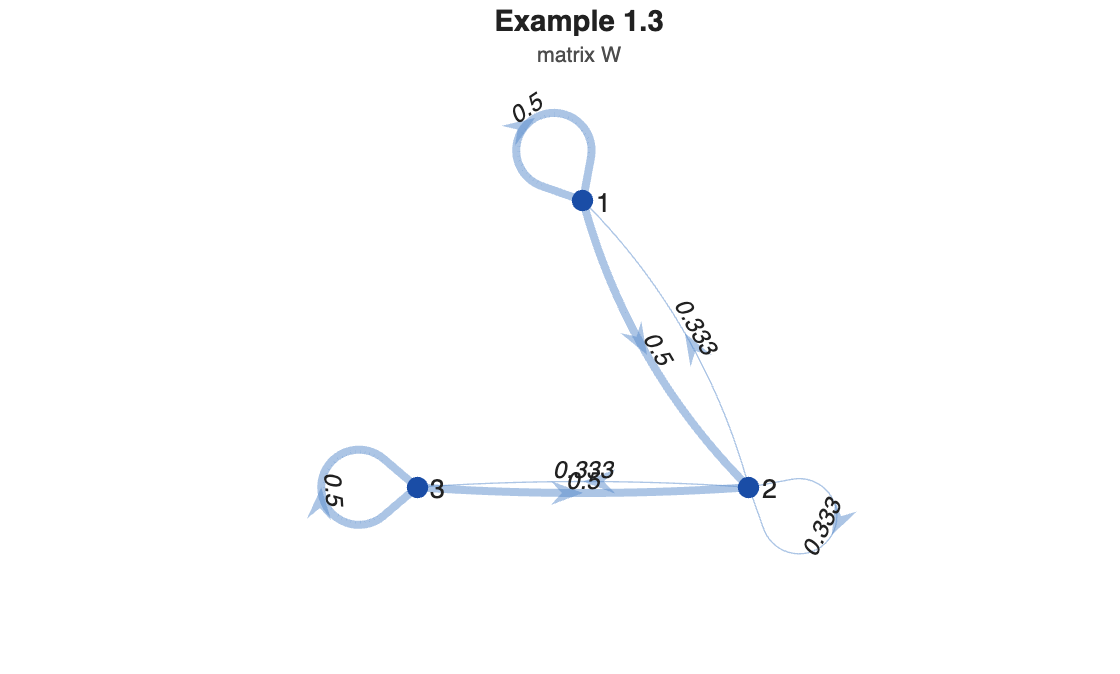

W = [1/2 1/2   0
     1/3 1/3 1/3
       0 1/2 1/2];
plot_graph(W, [], 'Title','Example 1.3', 'Subtitle','matrix W') 

`lot_graph(W, [], 'Title','Example 1.3', 'Subtitle','matrix W') `One can expect that the "central" node 2 corresponds to the most influential sgent in the group. Thisiis confirmed by a straightforward computation: solving the system of equation $p_\infty^T = p_\infty^TW$ and $p_\infty^T \mathbb 1 = 1$, one obtains the vector of social powers $p_\infty^T = (2/7, 3/7, 2/7)$

x0 = [3;-1;5]

x0 =      3
    -1
     5


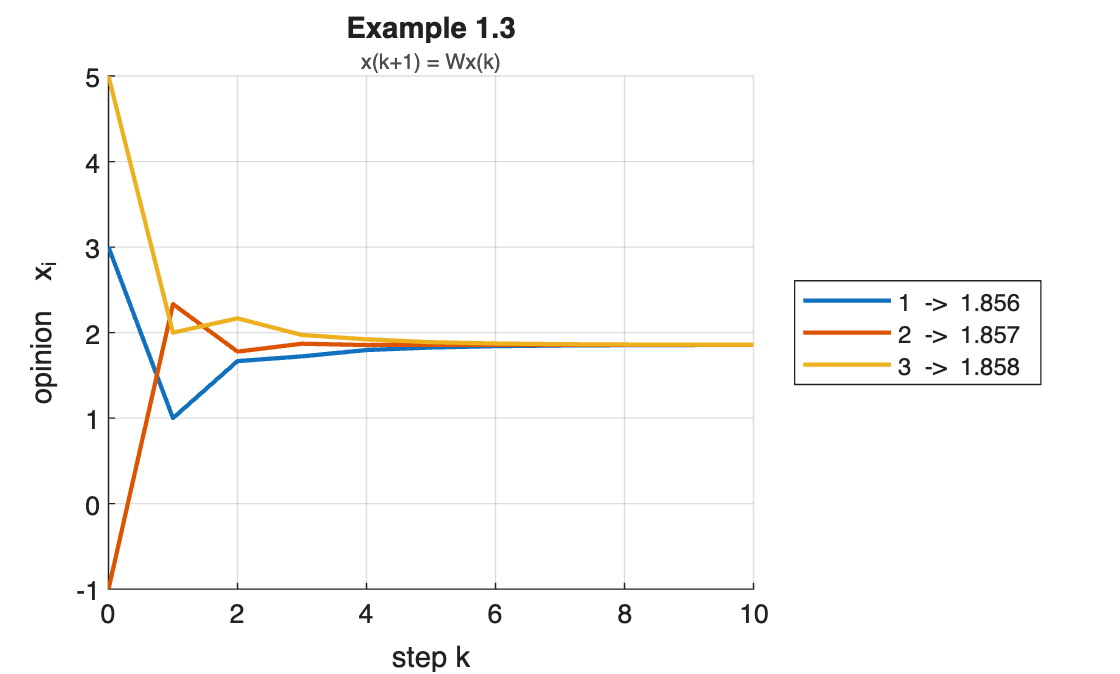

p  = social_power(W);          % p' = p'W,  p'1 = 1   ->  [2/7 3/7 2/7]
X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')

p' * x0                        % the consensus value

ans = 1.8571

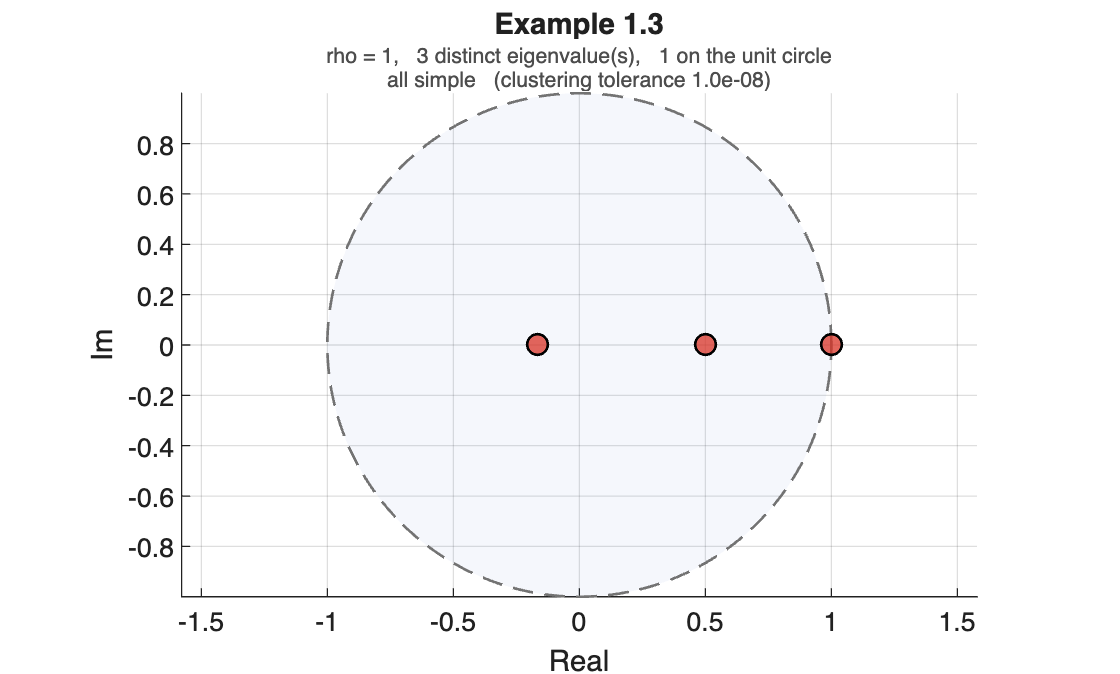

T = 3×5 table
     lambda        Re       Im    modulus    multiplicity
    ________    ________    __    _______    ____________

           1           1    0           1         1      
         0.5         0.5    0         0.5         1      
    -0.16667    -0.16667    0     0.16667         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','Example 1.3'); T

## 1.4 Stubborn agents in the French-DeGroot model

An agent is said to be **stubborn** if its opinion remains unchanged, independent of the other's opinions.

If the opinions obey the model  M1.1 then the agent $i$ is stubborn $x_i(k)\equiv x_i(0)$ $\iff$ $w_{ii}=1$. Such an agent corresponds to a source node in a graph $\mathcal G[W]$, ie a node having no incoming arcs but for the self-loop. **Theorem 1.1** implies that if $\mathcal G[W]$ has the only source, then the opinions reach a consensus (the source node is the opnly closed strong component of the graph).

If more than one stubborn agent exist (ie $\mathcal G[W]$ has several sources), then consensus among them is, obviously, impossible.  **Theorem 1.1** implies, however, that typically the opinions in such a group converge.

**Corollary 1.2 **Let the group have $s\ge1$ stubborn agents, influencing all other individuals (ie the set of source nodes is connected by walks to all other nodes of $\mathcal G[W]$. Then the model M1.1 is convergent.

Indeed, source nodes are the only closed strong components of $\mathcal G[W]$, which are obiously aperiodic.

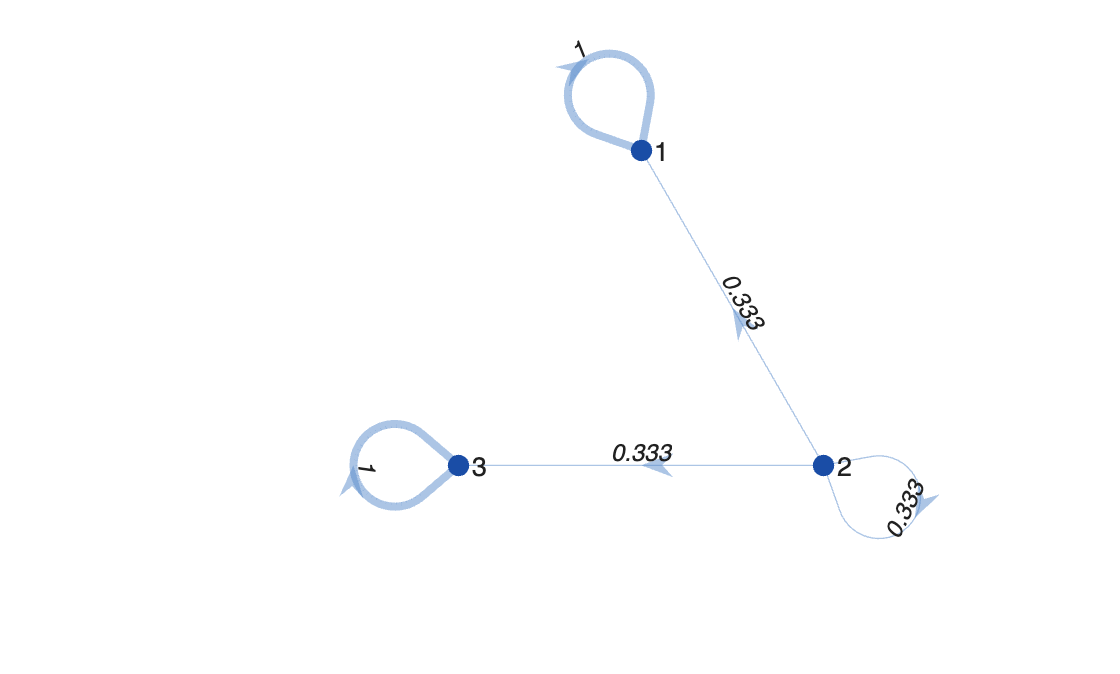

W = [1 0 0
     1/3 1/3 1/3
       0 0 1];
plot_graph(W, [], 'Title','Example 1.4', 'Subtitle','matrix W') 

x0 = [3;-1;5]

x0 =      3
    -1
     5


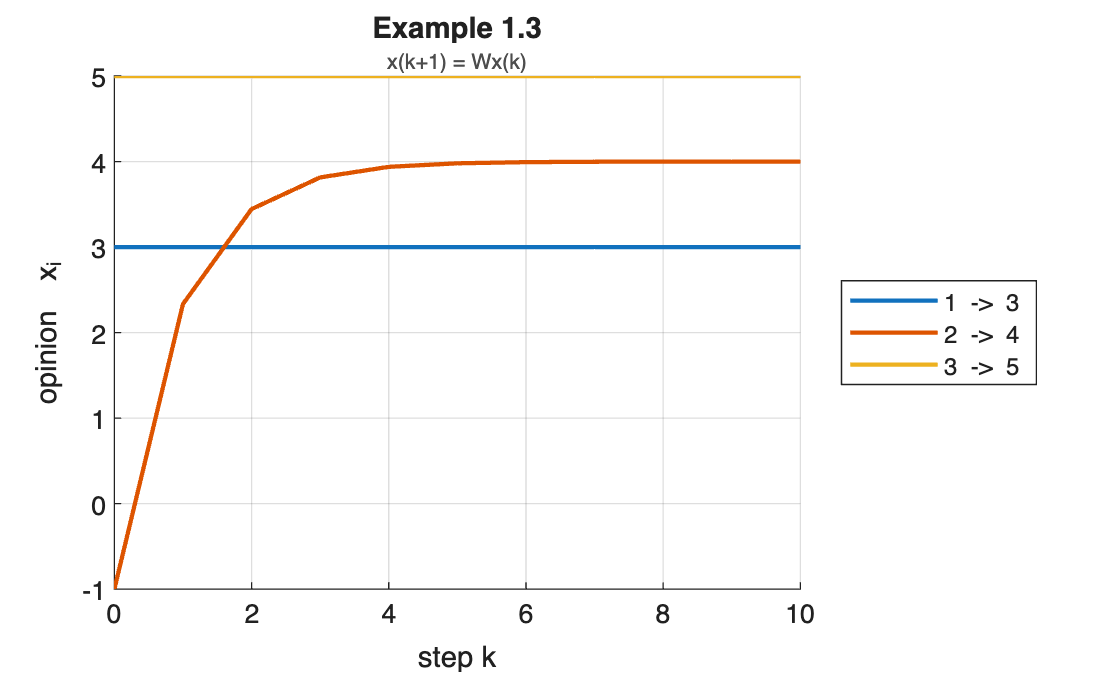

X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')

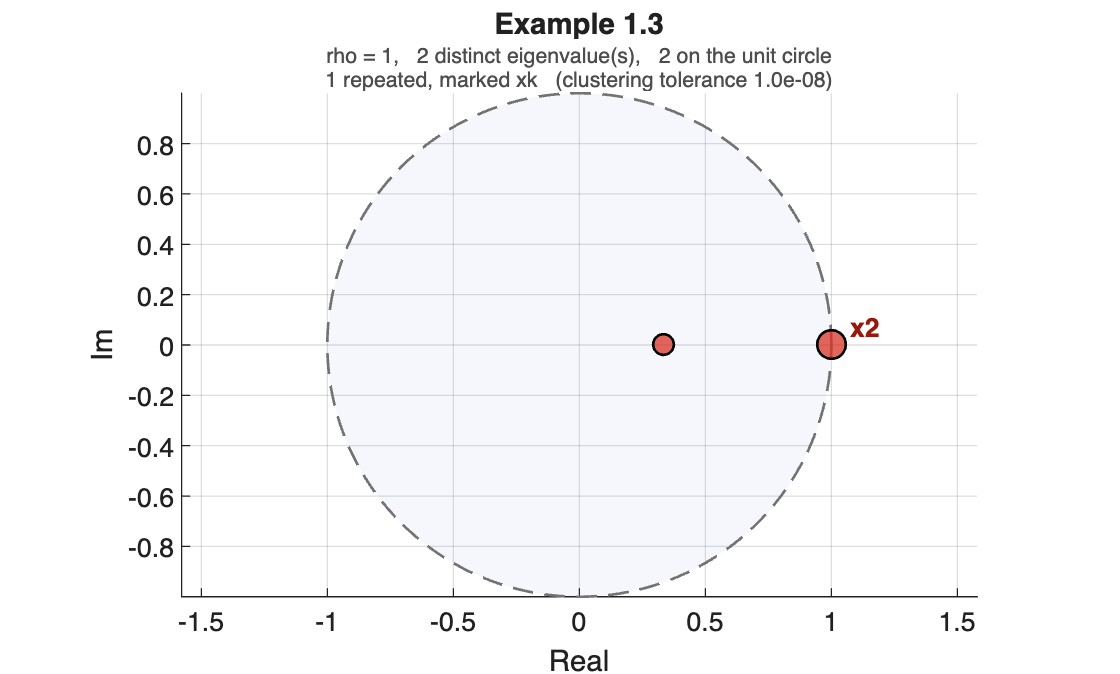

T = 2×5 table
    lambda       Re       Im    modulus    multiplicity
    _______    _______    __    _______    ____________

          1          1    0           1         2      
    0.33333    0.33333    0     0.33333         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','Example 1.3'); T

## 1.5 Examples

The same French-DeGroot model is applied to six topologies on N = 6 nodes. The number of agents, the initial condition and the horizon are identical in every example, so any difference in the outcome is attributable to the topology alone.

Each example follows the same six steps: topology, matrix and structural information, graph, state evolution, spectrum, short observation.

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];      % the same initial condition in every example
K  = 30;                        % the same horizon

fprintf('N = %d, mean x0 = %.4f\n', N, mean(x0));

N = 6, mean x0 = 1.1667


## 1.5.1 Directed cycle

Each agent listens only to its predecessor. The graph is strongly connected, so W is irreducible, but its only cycle has length 6: the graph is periodic with period 6.

A = common_topology('cycle');
W = row_stochastic(A)

W =      0     0     0     0     0     1
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [1 1 1 1 1 1]   weight-balanced: yes
  strong components  : 1   closed: 1   periods: 6
  rooted: yes   convergent: no    consensus: no


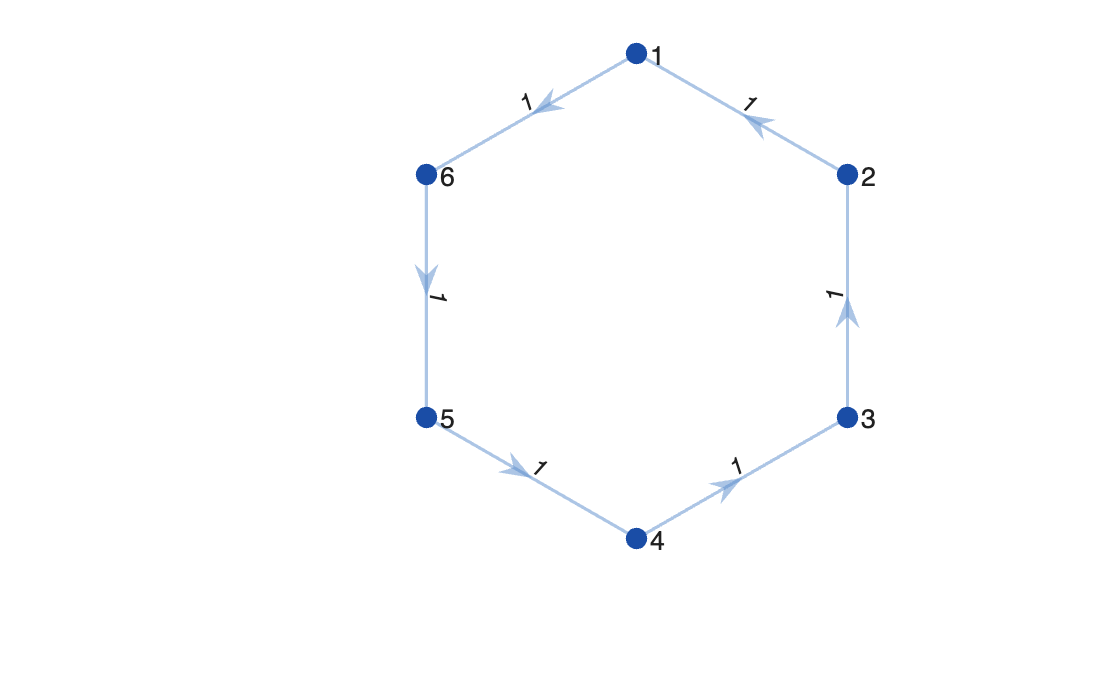

figure; plot_graph(W, [], 'Title','1.5.1 Directed cycle', 'Subtitle','W')

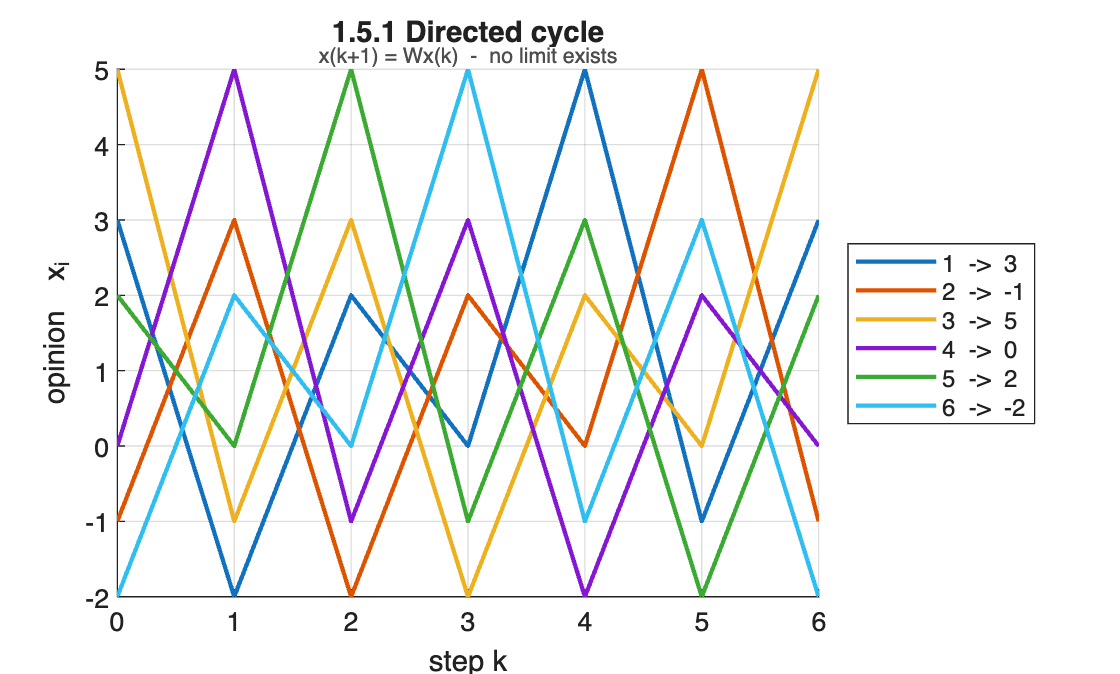

X = sim_degroot(W, x0, 6);
figure; plot_opinions(X, [], 'Title','1.5.1 Directed cycle', ...
                             'Subtitle','x(k+1) = Wx(k)  -  no limit exists')

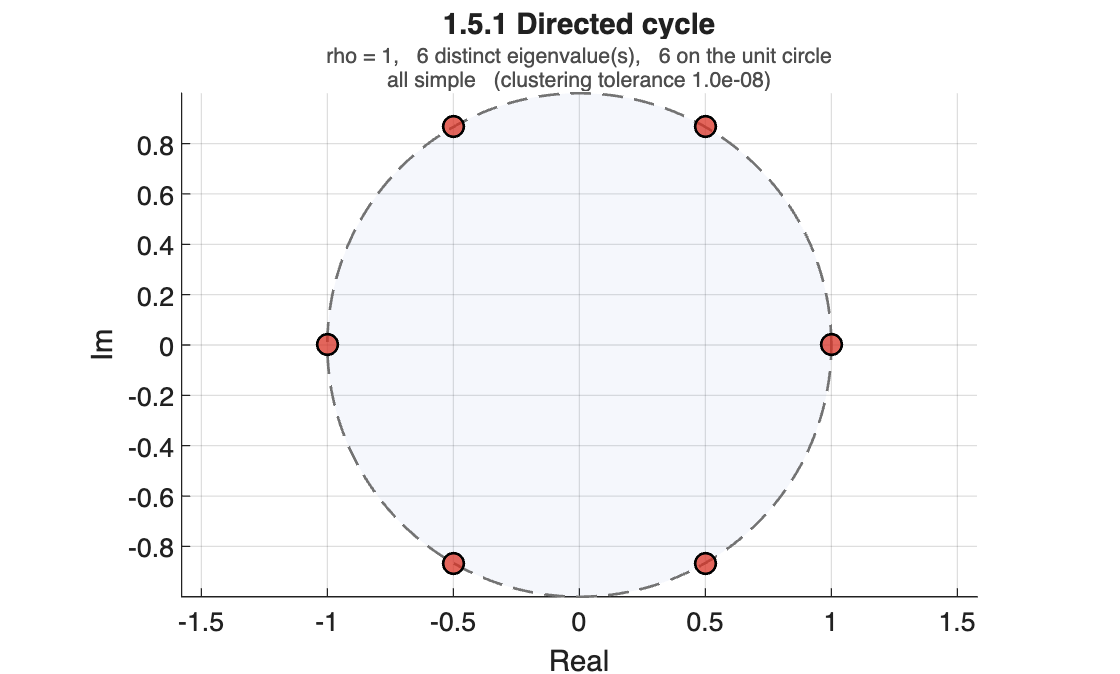

T = 6×5 table
       lambda         Re        Im       modulus    multiplicity
    _____________    ____    ________    _______    ____________

       1+0i             1           0       1            1      
    -0.5+0.86603i    -0.5     0.86603       1            1      
    -0.5-0.86603i    -0.5    -0.86603       1            1      
      -1+0i            -1           0       1            1      
     0.5+0.86603i     0.5     0.86603       1            1      
     0.5-0.86603i     0.5    -0.86603       1            1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.1 Directed cycle'); T

W is a permutation matrix: the opinions are passed round the ring unchanged and repeat with period 6. All six eigenvalues are simple and lie on the unit circle, so the eigenvalue 1 is not strictly dominant and the model is not convergent.

## 1.5.2 Directed cycle with one self-loop

The only change is a self-loop on agent 1. It creates a cycle of length 1, so the period becomes gcd(1,6) = 1 and W is primitive.

A = common_topology('cycle-self');
W = row_stochastic(A)

W =     0.5000         0         0         0         0    0.5000
    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [1.5 1 1 1 1 0.5]   weight-balanced: no
  strong components  : 1   closed: 1   periods: 1
  rooted: yes   convergent: yes   consensus: yes


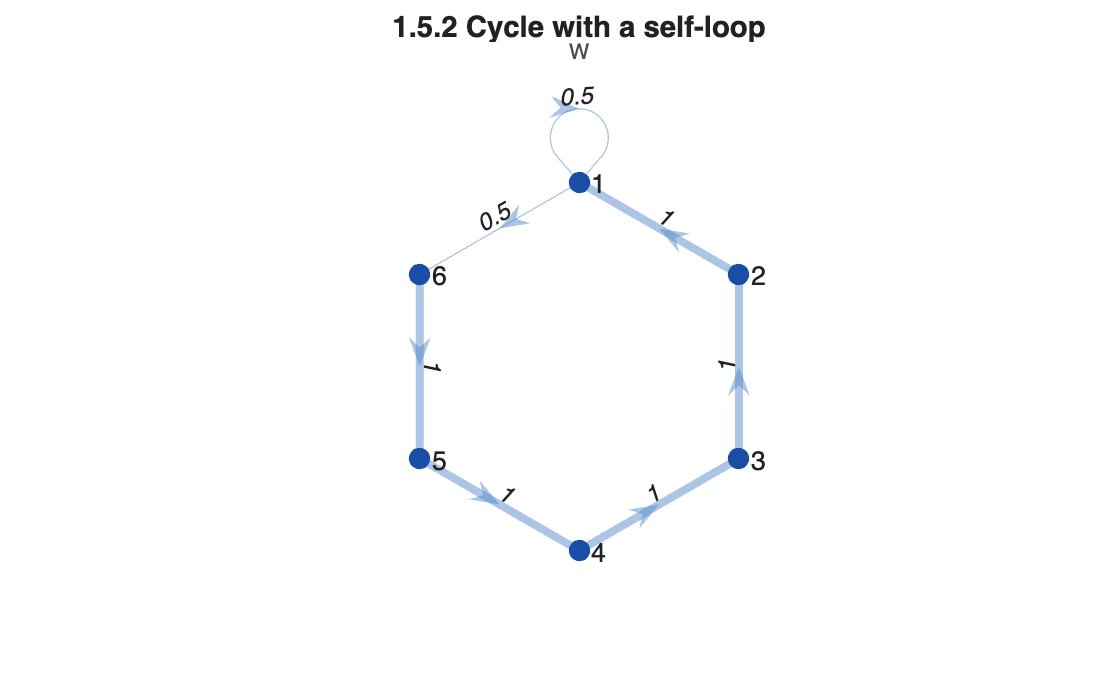

figure; plot_graph(W, [], 'Title','1.5.2 Cycle with a self-loop', 'Subtitle','W')

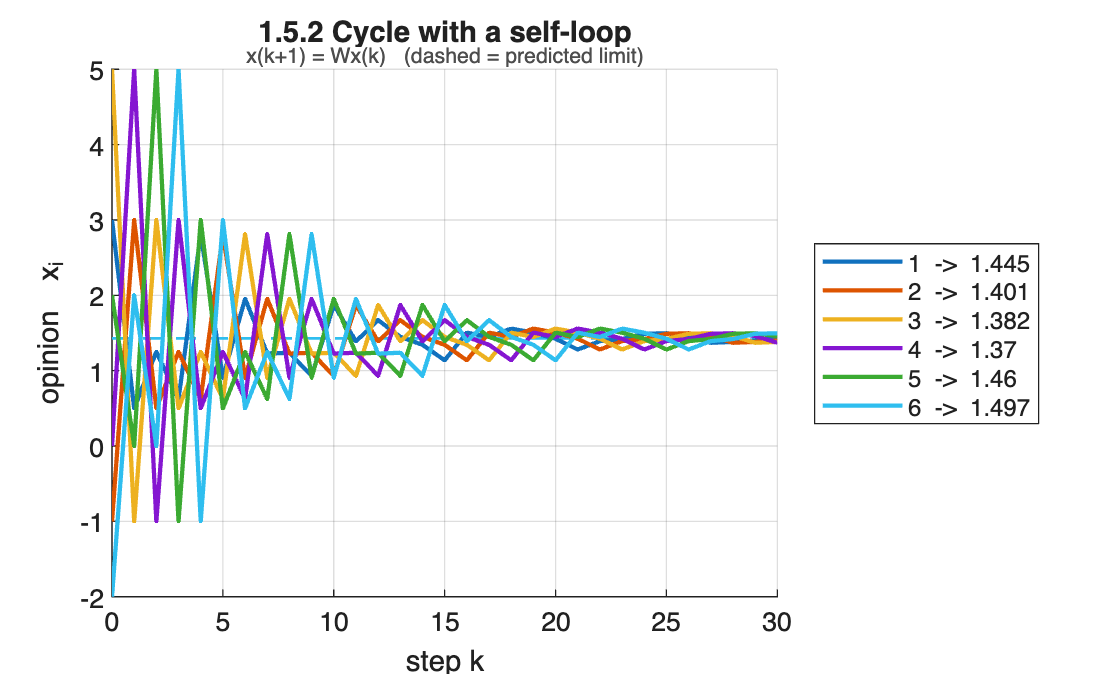

p    = social_power(W);
xinf = limit_matrix(W) * x0;
X    = sim_degroot(W, x0, K);
figure; plot_opinions(X, [], 'Limit', xinf, 'Title','1.5.2 Cycle with a self-loop', ...
                             'Subtitle','x(k+1) = Wx(k)   (dashed = predicted limit)')

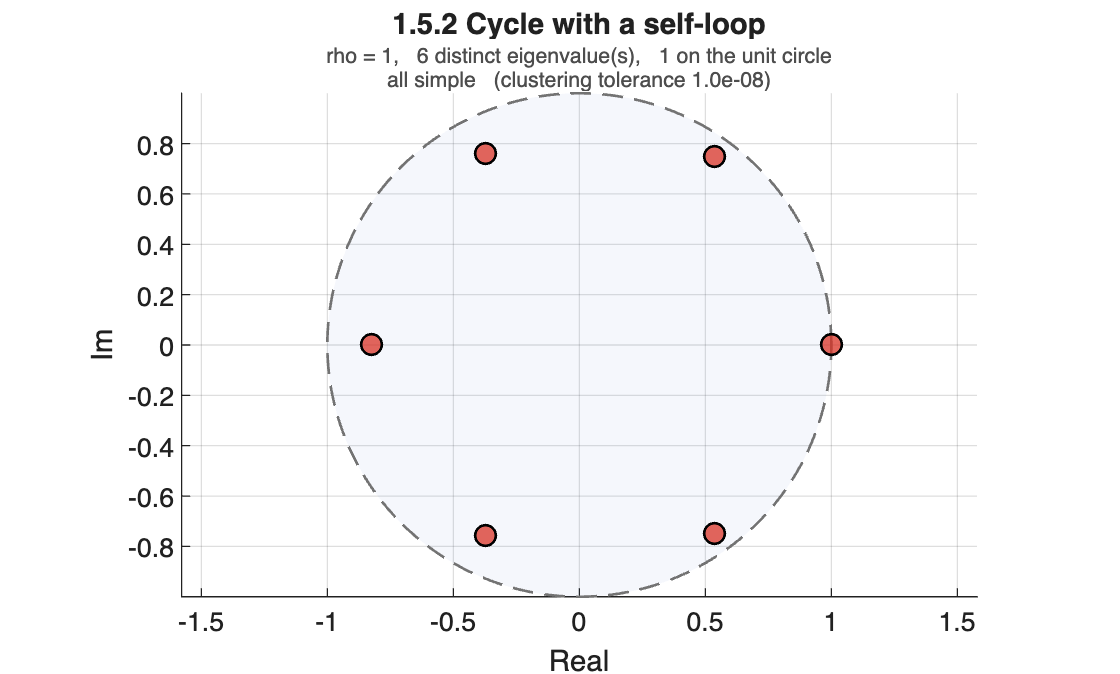

T = 6×5 table
         lambda            Re         Im       modulus    multiplicity
    ________________    ________    _______    _______    ____________

           1+0i                1          0          1         1      
     0.53484+0.7507i     0.53484     0.7507    0.92174         1      
     0.53484-0.7507i     0.53484    -0.7507    0.92174         1      
    -0.37327+0.7587i    -0.37327     0.7587    0.84555         1      
    -0.37327-0.7587i    -0.37327    -0.7587    0.84555         1      
    -0.82314+0i         -0.82314          0    0.82314         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.2 Cycle with a self-loop'); T

fprintf('social power p'' = %s\n', mat2str(round(p.',4)));

social power p' = [0.2857 0.1429 0.1429 0.1429 0.1429 0.1429]


fprintf('consensus value = %.4f\n', p.' * x0);

consensus value = 1.4286


One edge turns oscillation into consensus. The eigenvalue 1 is now simple and strictly dominant, and the group settles at px(0). Note that the self-loop also makes agent 1 the most influential agent, so the limit is not the plain average.

## 1.5.3 Directed line

A chain in which agent 1 listens only to itself and every other agent listens to its predecessor. The graph is not strongly connected, so W is reducible, but agent 1 is a globally reachable node and it is the only closed strong component.

A = common_topology('line');
W = row_stochastic(A)

W =      1     0     0     0     0     0
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [2 1 1 1 1 0]   weight-balanced: no
  strong components  : 6   closed: 1   periods: [0 0 0 0 0 1]
  rooted: yes   convergent: yes   consensus: yes


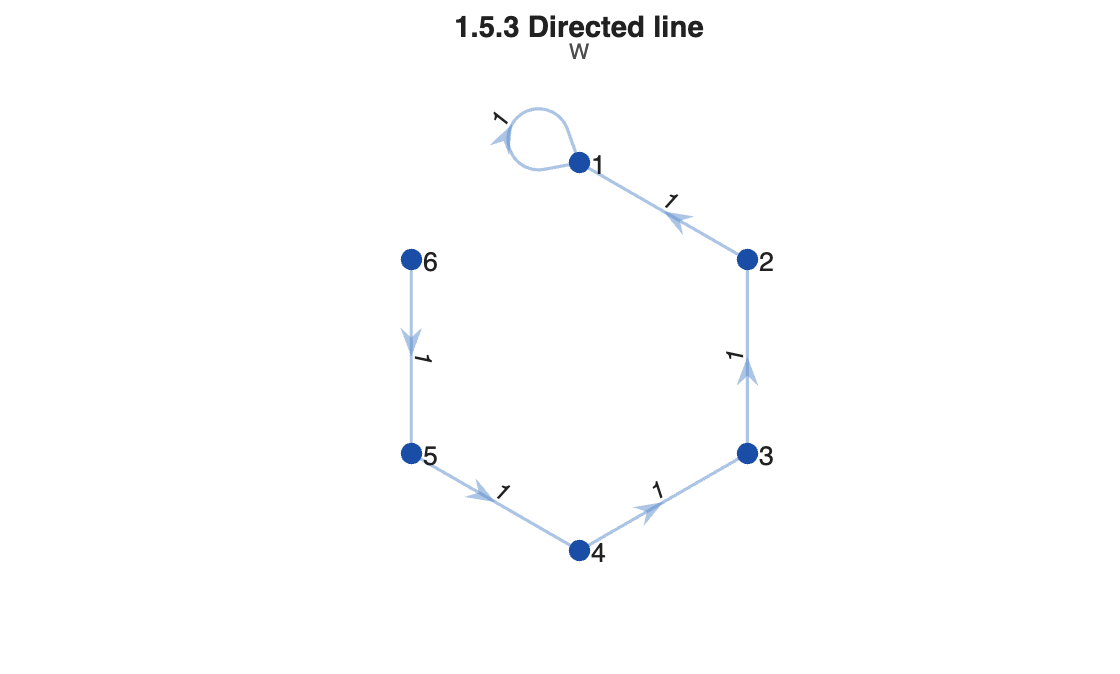

figure; plot_graph(W, [], 'Title','1.5.3 Directed line', 'Subtitle','W')

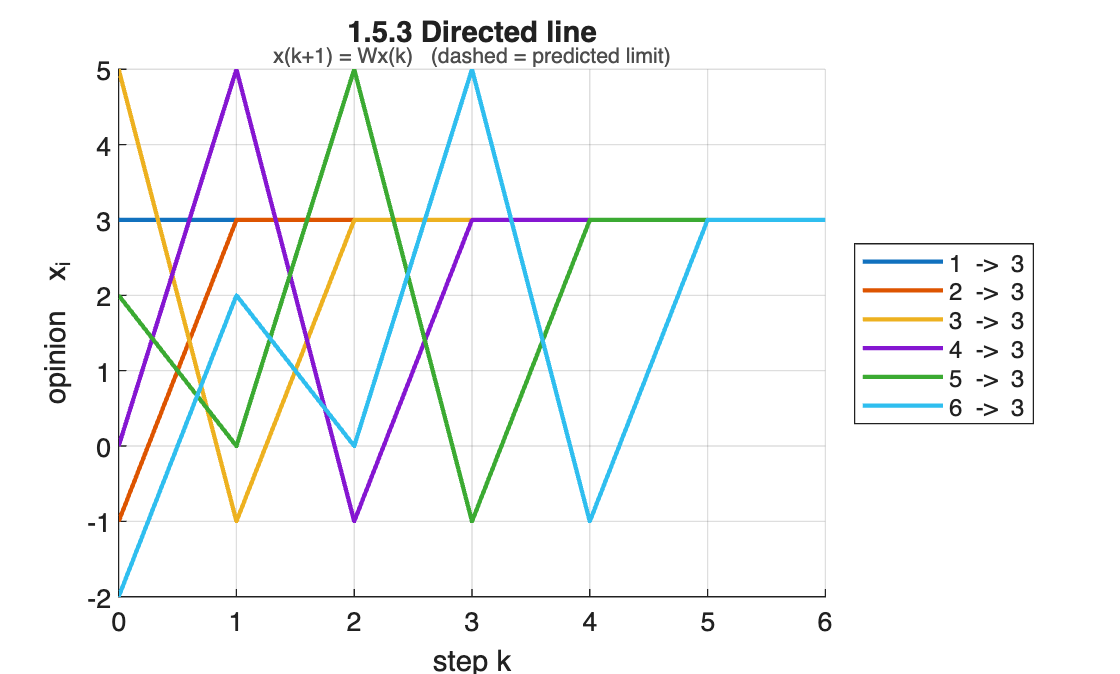

xinf = limit_matrix(W) * x0;
X    = sim_degroot(W, x0, 6);
figure; plot_opinions(X, [], 'Limit', xinf, 'Title','1.5.3 Directed line', ...
                             'Subtitle','x(k+1) = Wx(k)   (dashed = predicted limit)')

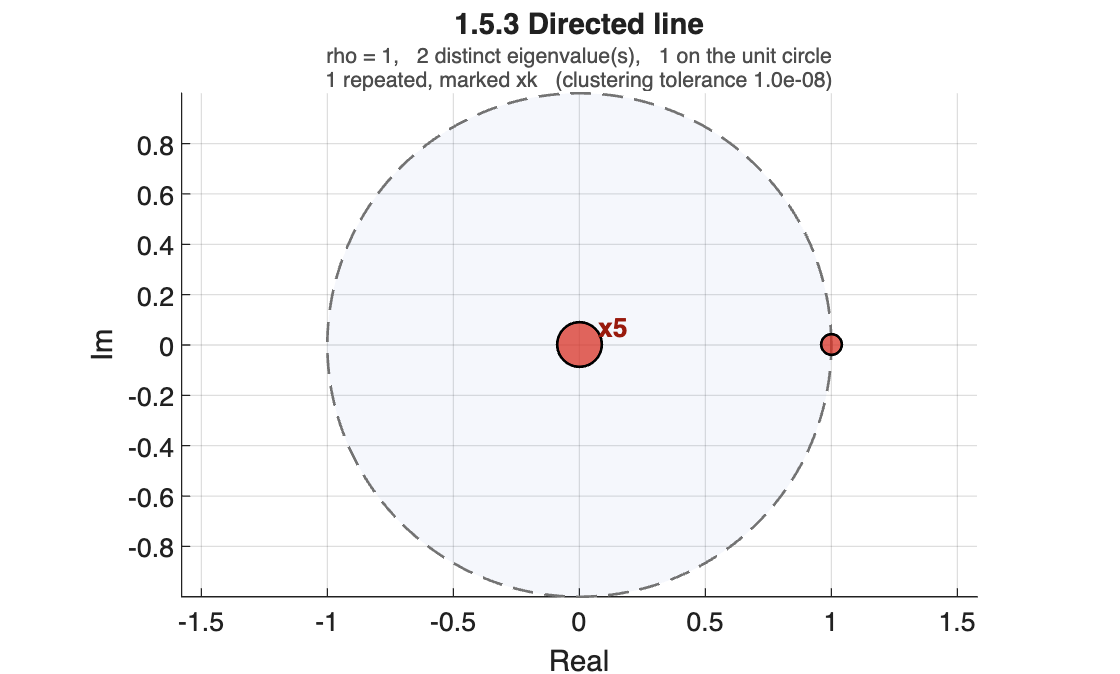

T = 2×5 table
    lambda    Re    Im    modulus    multiplicity
    ______    __    __    _______    ____________

      1       1     0        1            1      
      0       0     0        0            5      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.3 Directed line'); T

fprintf('social power p'' = %s\n', mat2str(round(social_power(W).',4)));

social power p' = [1 0 0 0 0 0]


fprintf('consensus value = %.4f   (= x1(0) = %.4f)\n', xinf(1), x0(1));

consensus value = 3.0000   (= x1(0) = 3.0000)


Consensus is reached at the initial opinion of the single source: every other initial opinion is forgotten, and the social power vector is e1. The spectrum shows the eigenvalue 0 with multiplicity 5, which is why the limit is attained exactly after 5 steps rather than asymptotically.

## 1.5.4 Bidirectional star

A hub connected to five leaves in both directions. The graph is strongly connected, but every closed walk alternates between hub and leaves, so all cycles have even length and the period is 2.

A = common_topology('star');
W = row_stochastic(A)

W =          0    0.2000    0.2000    0.2000    0.2000    0.2000
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [5 0.2 0.2 0.2 0.2 0.2]   weight-balanced: no
  strong components  : 1   closed: 1   periods: 2
  rooted: yes   convergent: no    consensus: no


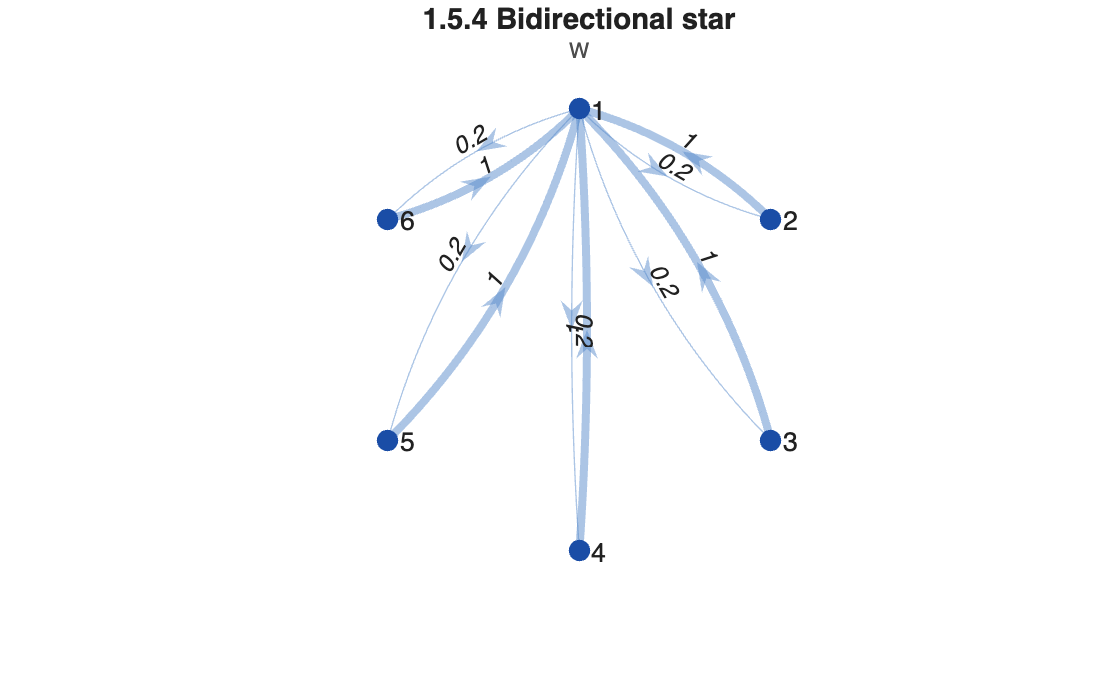

figure; plot_graph(W, [], 'Title','1.5.4 Bidirectional star', 'Subtitle','W')

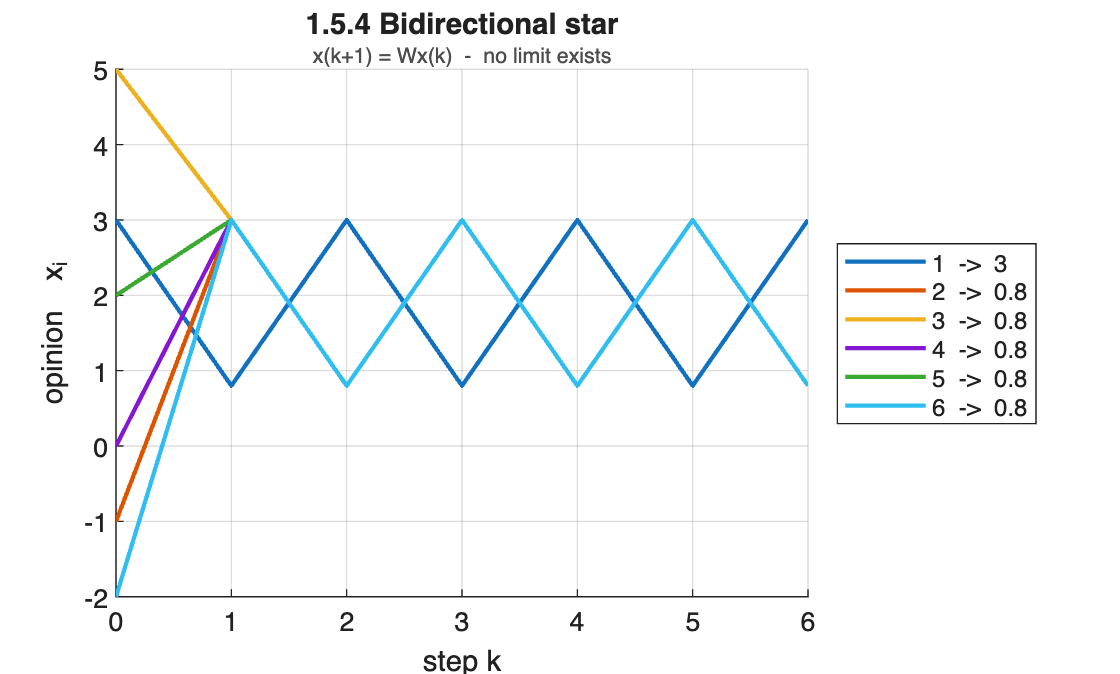

X = sim_degroot(W, x0, 6);
figure; plot_opinions(X, [], 'Title','1.5.4 Bidirectional star', ...
                             'Subtitle','x(k+1) = Wx(k)  -  no limit exists')

figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.4 Bidirectional star'); T

T = 3×5 table
    lambda    Re    Im    modulus    multiplicity
    ______    __    __    _______    ____________

      -1      -1    0        1            1      
       1       1    0        1            1      
       0       0    0        0            4      


The eigenvalue -1 sits on the unit circle beside 1, so the model is not convergent: hub and leaves swap their averages at every step. The spectrum also shows the eigenvalue 0 with multiplicity 4, which the multiplicity marker makes visible; a plain scatter would show a single point at the origin.

## 1.5.5 Out-star: a topology the standard formulation cannot use

Here the hub listens to all the leaves and the leaves listen to nobody. Their out-degrees are zero, so D_out is singular and the row-stochastic matrix W = D_out^{-1} A does not exist. The topology is perfectly legitimate; it is the normalisation that fails.

The standard remedy is the Perron matrix P = I - eps*L, with eps <= 1 / max_i d_out(i). It is row-stochastic by construction, needs no inverse, and leaves the graph unchanged.

A = common_topology('star-out');
matrix_report(A, 'A');          % the report flags the singular D_out

A   (6 agents)
  out-degrees (row sums): [5 0 0 0 0 0]   row-stochastic : no
  in-degrees  (col sums): [0 1 1 1 1 1]   weight-balanced: no
  strong components  : 6   closed: 5   periods: [0 0 0 0 0 0]
  rooted: no    convergent: yes   consensus: no
  NOTE: agents [2 3 4 5 6] have out-degree 0, so D_out is singular and
        W = D_out^{-1} A does not exist. Use P = I - eps*L.


eps = 1 / max(sum(A,2));        % the largest admissible step
P   = eye(N) - eps * laplacian(A)

P =          0    0.2000    0.2000    0.2000    0.2000    0.2000
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


s   = matrix_report(P, 'P');

P   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [0 1.2 1.2 1.2 1.2 1.2]   weight-balanced: no
  strong components  : 6   closed: 5   periods: [0 1 1 1 1 1]
  rooted: no    convergent: yes   consensus: no


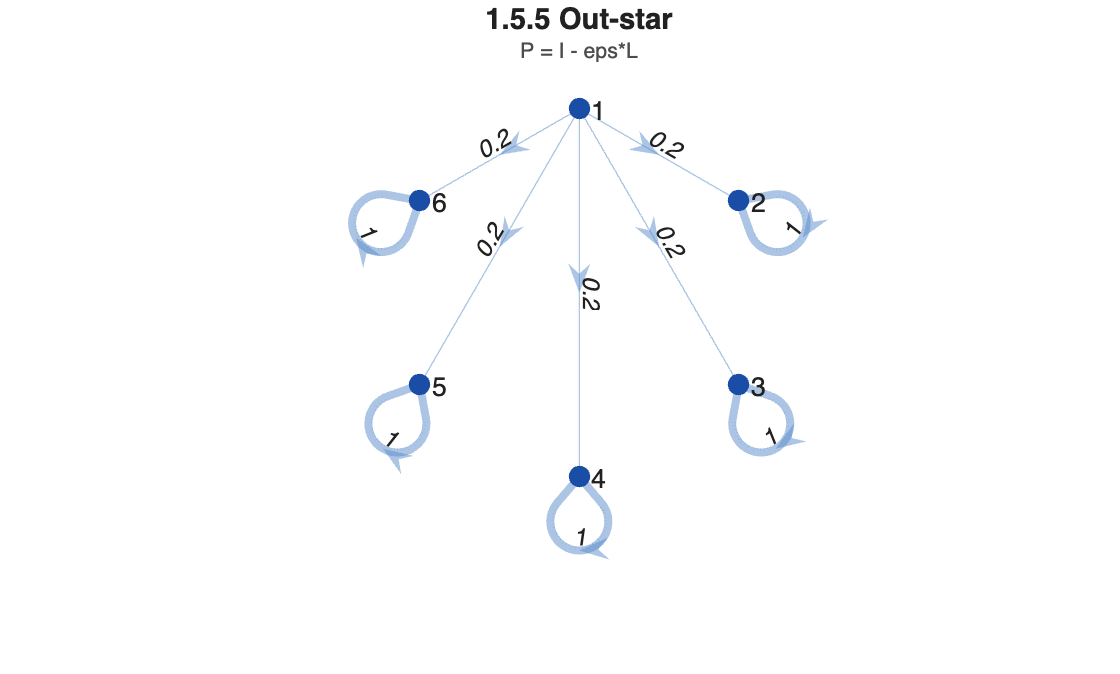

figure; plot_graph(P, [], 'Title','1.5.5 Out-star', 'Subtitle','P = I - eps*L')

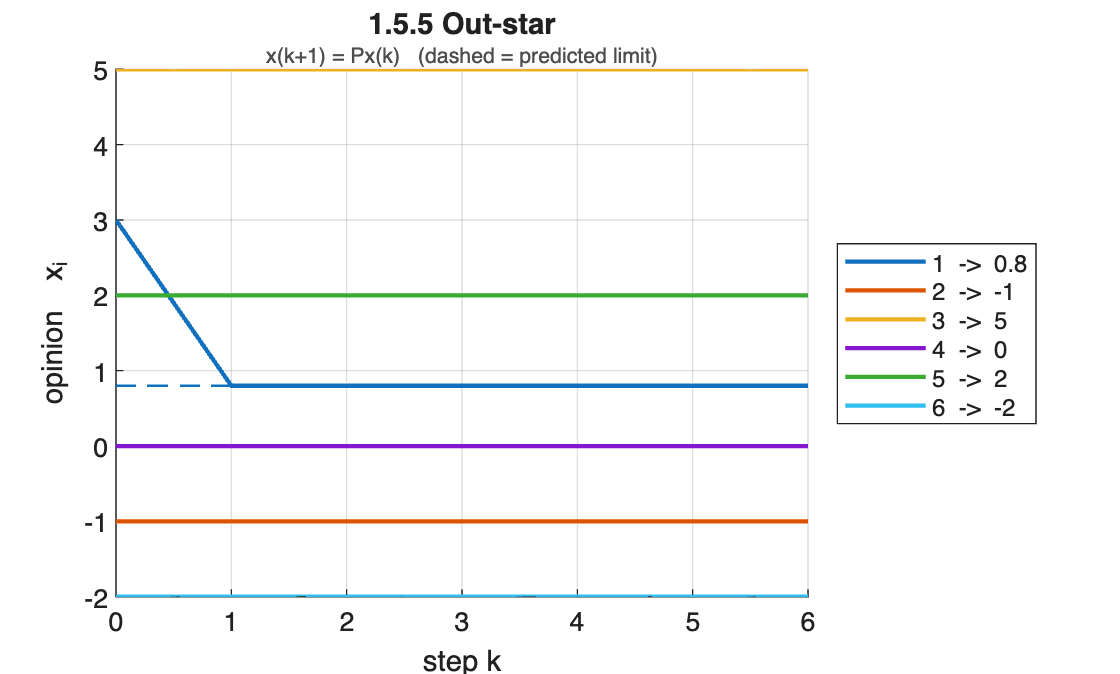

xinf = limit_matrix(P) * x0;
X    = sim_degroot(P, x0, 6);
figure; plot_opinions(X, [], 'Limit', xinf, 'Title','1.5.5 Out-star', ...
                             'Subtitle','x(k+1) = Px(k)   (dashed = predicted limit)')

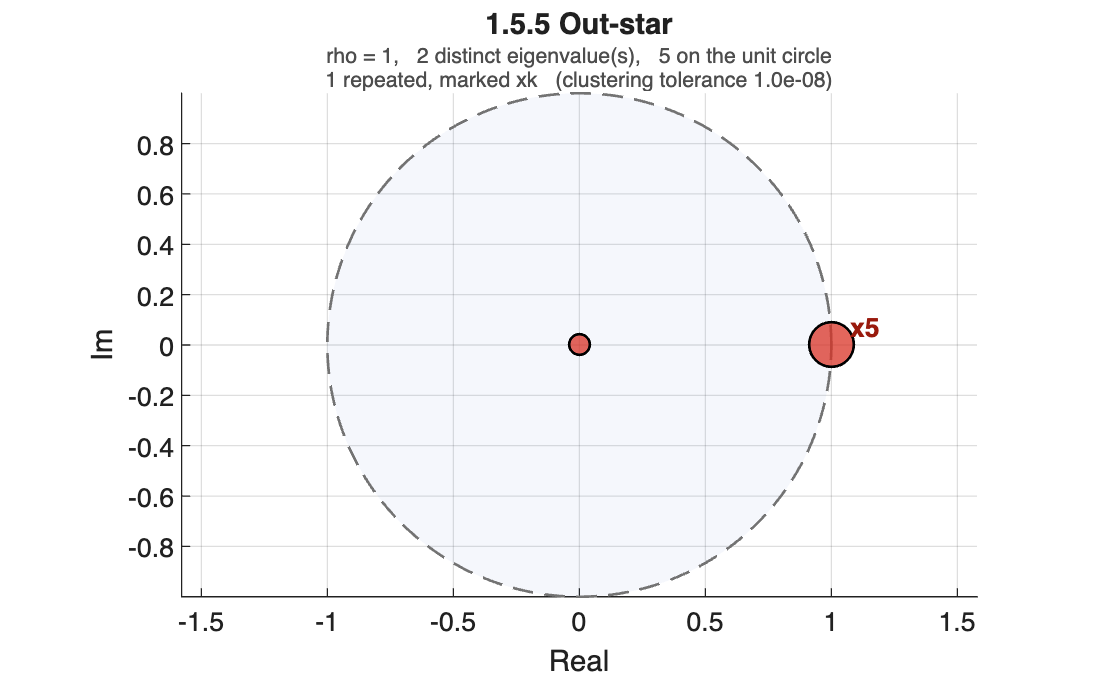

T = 2×5 table
    lambda    Re    Im    modulus    multiplicity
    ______    __    __    _______    ____________

      1       1     0        1            5      
      0       0     0        0            1      


figure; T = plot_eigenvalues(P, 'discrete', 'Title','1.5.5 Out-star'); T

fprintf('x(inf) = %s\n', mat2str(round(xinf.',4)));

x(inf) = [0.8 -1 5 0 2 -2]


fprintf('mean of the leaves = %.4f\n', mean(x0(2:N)));

mean of the leaves = 0.8000


The five leaves have no incoming information and keep their initial opinions forever, so the eigenvalue 1 has multiplicity 5 and consensus is impossible. The hub reaches the average of the leaves in a single step. The model converges, but not to a consensus.

## 1.5.6 Two disjoint blocks

Two complete triangles with no edge between them. The graph has two closed strong components, each aperiodic.

A = common_topology('two-blocks');
W = row_stochastic(A)

W =          0    0.5000    0.5000         0         0         0
    0.5000         0    0.5000         0         0         0
    0.5000    0.5000         0         0         0         0
         0         0         0         0    0.5000    0.5000
         0         0         0    0.5000         0    0.5000
         0         0         0    0.5000    0.5000         0


s = matrix_report(W, 'W');

W   (6 agents)
  out-degrees (row sums): [1 1 1 1 1 1]   row-stochastic : yes
  in-degrees  (col sums): [1 1 1 1 1 1]   weight-balanced: yes
  strong components  : 2   closed: 2   periods: [1 1]
  rooted: no    convergent: yes   consensus: no


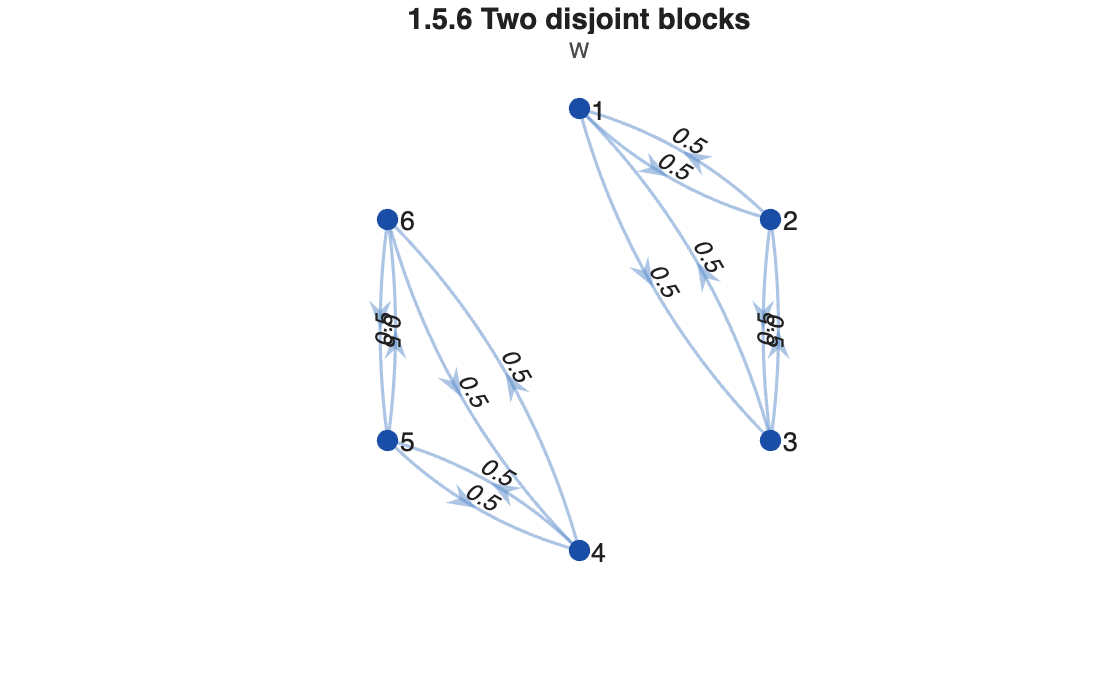

figure; plot_graph(W, [], 'Title','1.5.6 Two disjoint blocks', 'Subtitle','W')

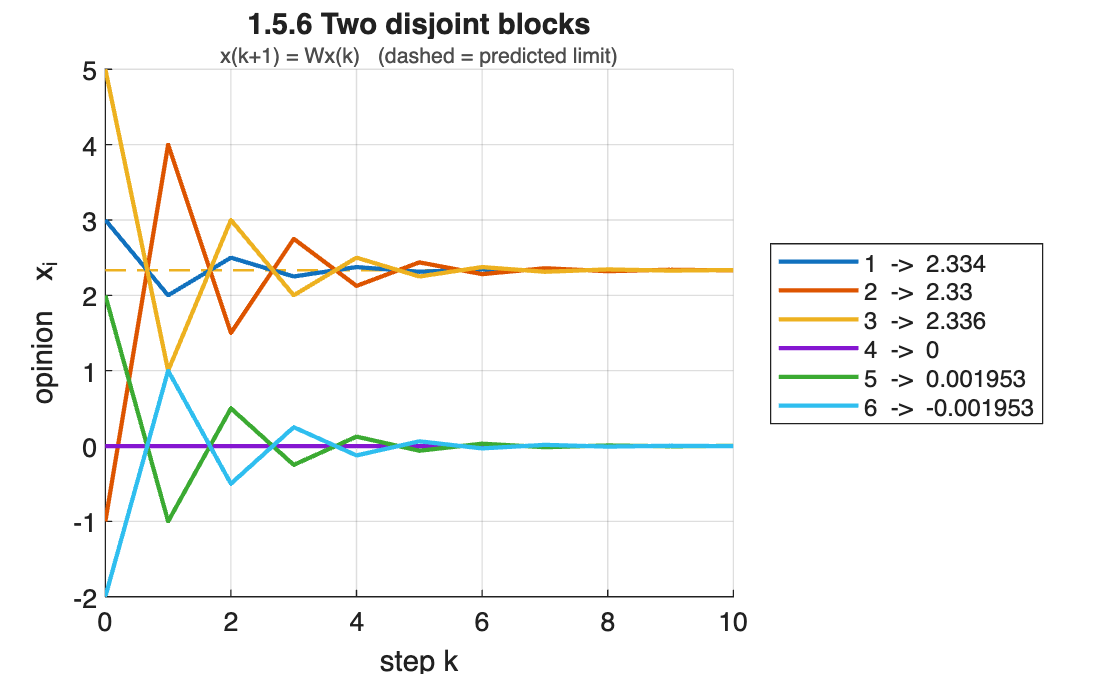

xinf = limit_matrix(W) * x0;
X    = sim_degroot(W, x0, 10);
figure; plot_opinions(X, [], 'Limit', xinf, 'Title','1.5.6 Two disjoint blocks', ...
                             'Subtitle','x(k+1) = Wx(k)   (dashed = predicted limit)')

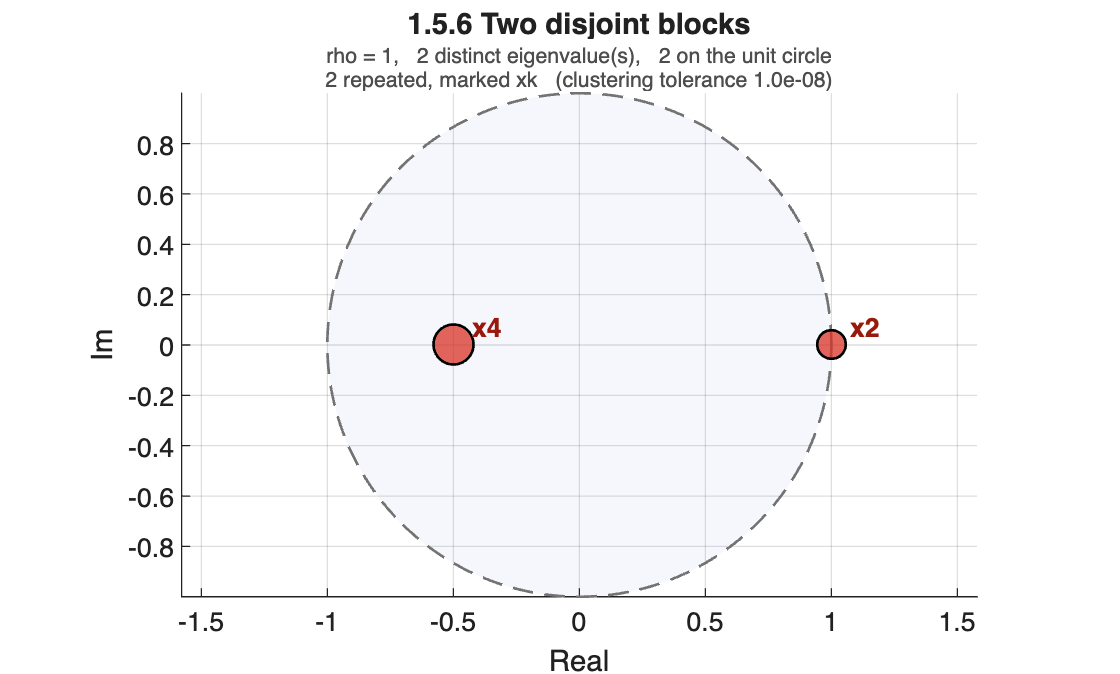

T = 2×5 table
    lambda     Re     Im    modulus    multiplicity
    ______    ____    __    _______    ____________

        1        1    0         1           2      
     -0.5     -0.5    0       0.5           4      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','1.5.6 Two disjoint blocks'); T

fprintf('block means: %.4f and %.4f\n', mean(x0(1:3)), mean(x0(4:6)));

block means: 2.3333 and 0.0000


fprintf('rank of W^inf = %d\n', rank(limit_matrix(W)));

rank of W^inf = 2


Each block agrees internally, at its own average, and the two never meet. The eigenvalue 1 has multiplicity 2, one for each closed component: this is the algebraic signature of disagreement, and it is exactly what the multiplicity marker is there to expose.

## 1.5.7 Comparison

The same model on six topologies. The multiplicity of the eigenvalue 1 is the quantity that decides the outcome: 1 gives consensus, more than 1 gives disagreement, and an eigenvalue of modulus 1 other than 1 itself gives no limit at all.

names = {'cycle','cycle-self','line','star','star-out','two-blocks'};
rows  = cell(numel(names),1);

for i = 1:numel(names)
    A = common_topology(names{i});
    if any(sum(A,2) == 0)                       % out-star: use the Perron matrix
        M = eye(N) - (1/max(sum(A,2))) * laplacian(A);
    else
        M = row_stochastic(A);
    end
    s = graph_summary(M);
    T = plot_eigenvalues(M, 'discrete', 'Plot', false);      % table only
    mult1 = sum(T.multiplicity(abs(T.lambda - 1) < 1e-8));
    onCircle = sum(T.multiplicity(abs(abs(T.lambda) - 1) < 1e-8));
    if s.convergent
        spread = max(limit_matrix(M)*x0) - min(limit_matrix(M)*x0);
    else
        spread = NaN;
    end
    rows{i} = {names{i}, s.rooted, s.convergent, s.consensus, mult1, onCircle, spread};
end

recap = cell2table(vertcat(rows{:}), 'VariableNames', ...
    {'topology','rooted','convergent','consensus','mult_lambda1','on_unit_circle','final_spread'})

recap = 6×7 table
       topology       rooted    convergent    consensus    mult_lambda1    on_unit_circle    final_spread
    ______________    ______    __________    _________    ____________    ______________    ____________

    {'cycle'     }    true        false         false           1                6                   NaN 
    {'cycle-self'}    true        true          true            1                1            4.4409e-16 
    {'line'      }    true        true          true            1                1                     0 
    {'star'      }    true        false         false           1                2                   NaN 
    {'star-out'  }    false       true          false           5                5                     7 
 

Reading the table: consensus holds exactly when the graph is rooted and the eigenvalue 1 is simple. The cycle and the star are rooted but carry extra eigenvalues on the unit circle, so they never settle. The out-star and the two blocks settle but disagree, and the multiplicity of 1 counts the number of independent limits.